clc
clear
Bus1_Load1 = readtable("ConsumptionProfiles.xls",'Sheet','Bus1_Load1');
Bus1_Load2 = readtable("ConsumptionProfiles.xls",'Sheet','Bus1_Load2');
Bus2_Load1 = readtable("ConsumptionProfiles.xls",'Sheet','Bus2_Load1');
Bus3_Load1 = readtable("ConsumptionProfiles.xls",'Sheet','Bus3_Load1');
Bus3_Load2 = readtable("ConsumptionProfiles.xls",'Sheet','Bus3_Load2');
Bus3_Load3 = readtable("ConsumptionProfiles.xls",'Sheet','Bus3_Load3');
Bus4_Load1 = readtable("ConsumptionProfiles.xls",'Sheet','Bus4_Load1');
Bus5_Load1 = readtable("ConsumptionProfiles.xls",'Sheet','Bus5_Load1');
Bus6_Load1 = readtable("ConsumptionProfiles.xls",'Sheet','Bus6_Load1');
Bus6_Load2 = readtable("ConsumptionProfiles.xls",'Sheet','Bus6_Load2');
Bus6_Load3 = readtable("ConsumptionProfiles.xls",'Sheet','Bus6_Load3');
Bus7_Load1 = readtable("ConsumptionProfiles.xls",'Sheet','Bus7_Load1');
Bus7_Load2 = readtable("ConsumptionProfiles.xls",'Sheet','Bus7_Load2');
Bus8_Load1 = readtable("ConsumptionProfiles.xls",'Sheet','Bus8_Load1');
% Bus9_Load1 = readtable("ConsumptionProfiles.xls",'Sheet','Bus9_Load1');
Bus9_Load2 = readtable("ConsumptionProfiles.xls",'Sheet','Bus9_Load2');
Bus10_Load1 = readtable("ConsumptionProfiles.xls",'Sheet','Bus10_Load1');
Bus10_Load2 = readtable("ConsumptionProfiles.xls",'Sheet','Bus10_Load2');
Bus11_Load1 = readtable("ConsumptionProfiles.xls",'Sheet','Bus11_Load1');
% Bus11_Load2 = readtable("ConsumptionProfiles.xls",'Sheet','Bus11_Load2');
Bus11_Load3 = readtable("ConsumptionProfiles.xls",'Sheet','Bus11_Load3');
Bus12_Load1 = readtable("ConsumptionProfiles.xls",'Sheet','Bus12_Load1');
Bus13_Load1 = readtable("ConsumptionProfiles.xls",'Sheet','Bus13_Load1');

timestamp = Bus1_Load1.timestamp;

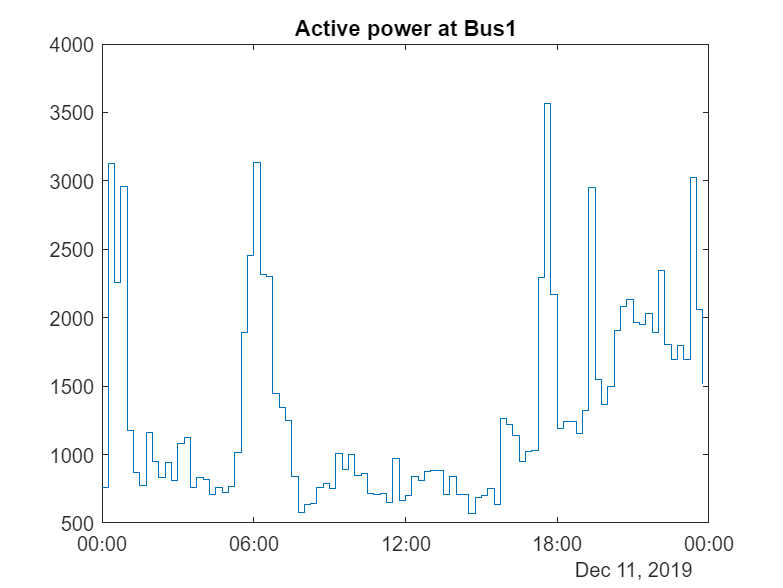

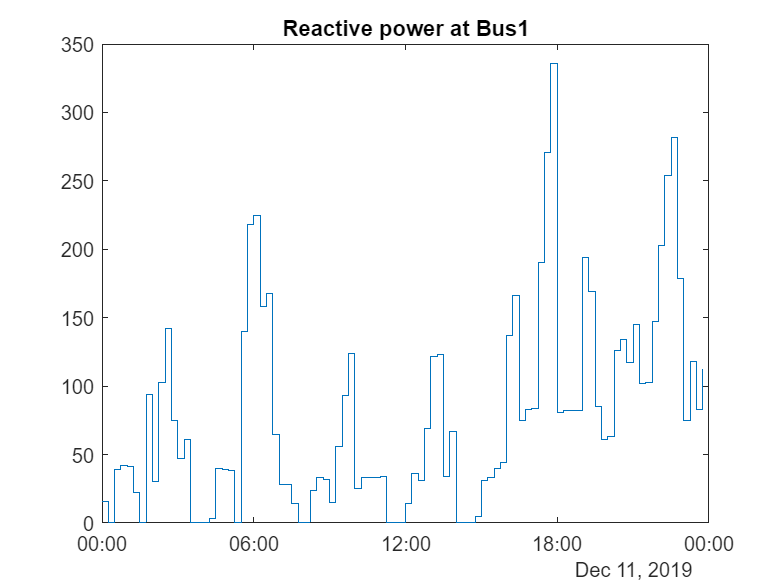

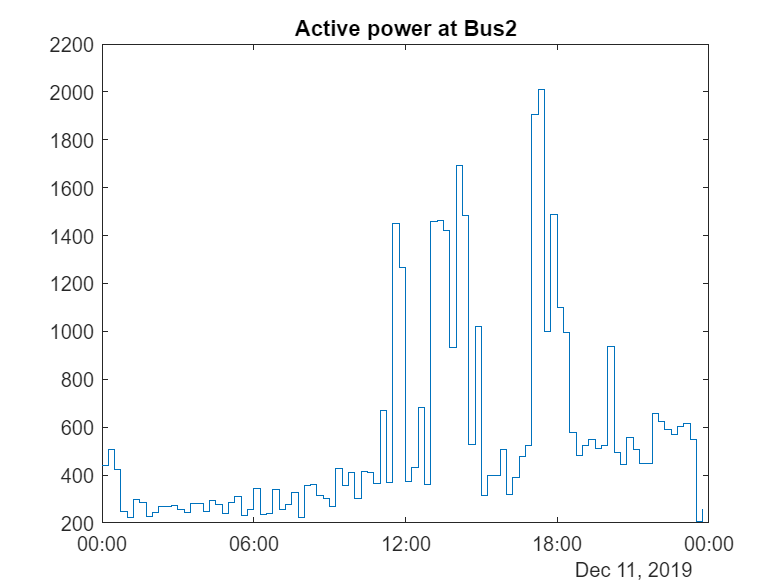

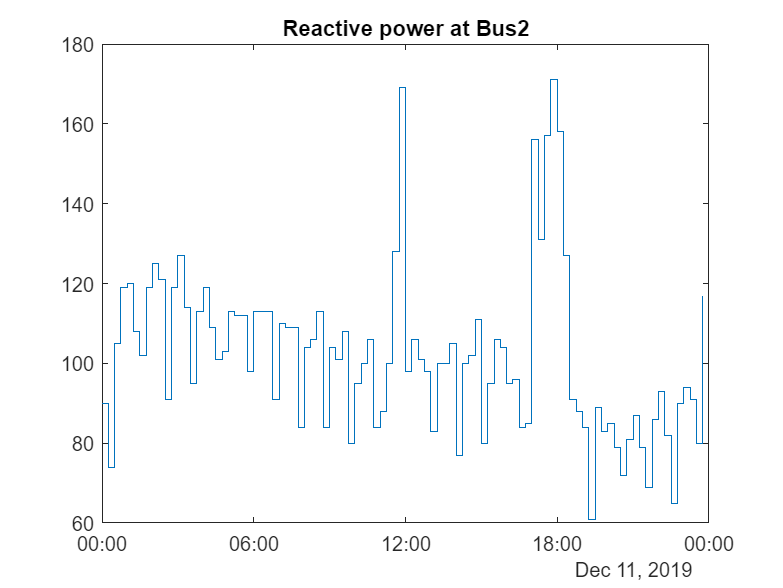

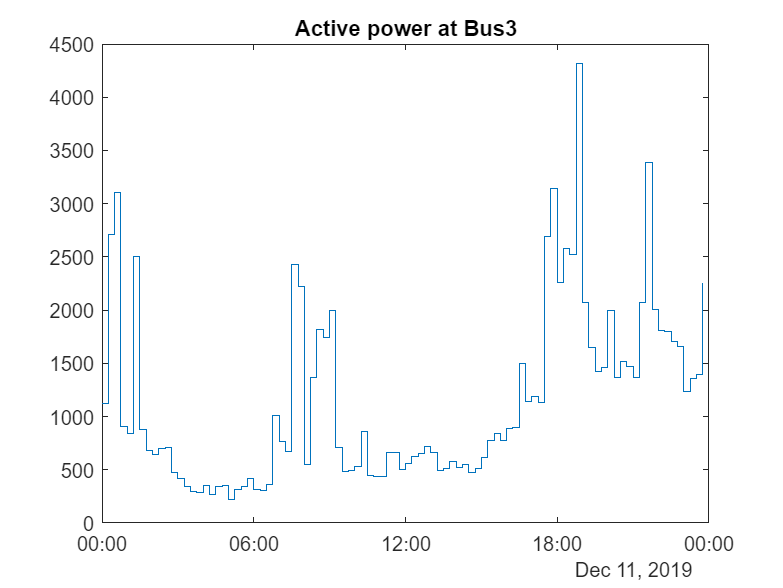

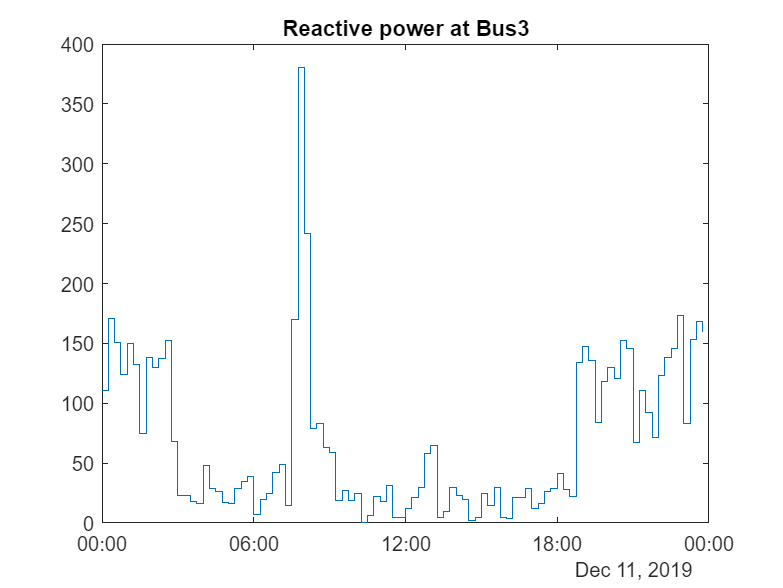

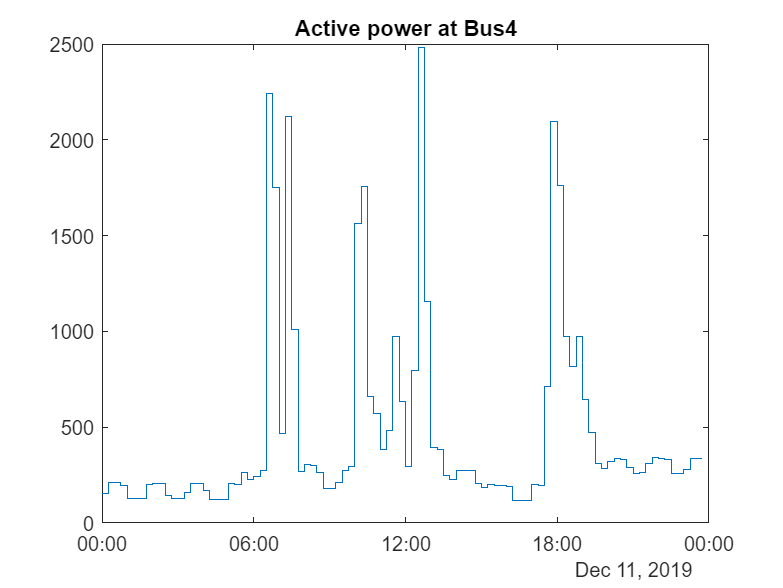

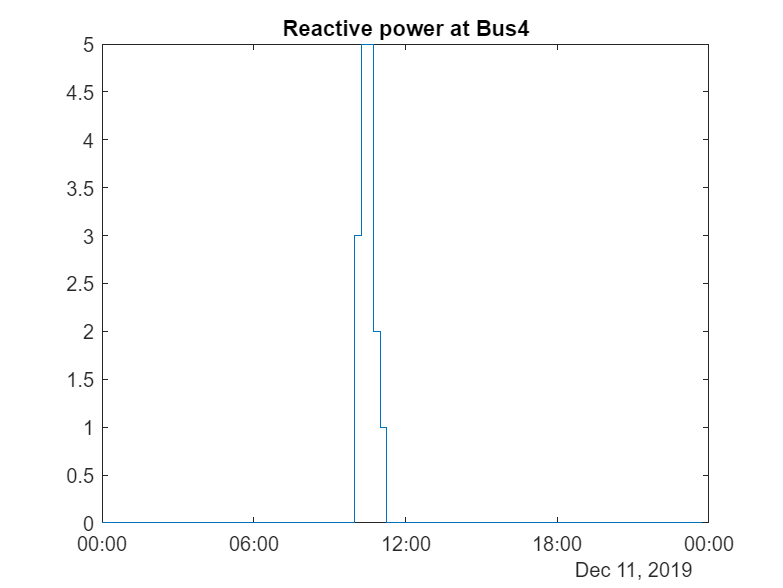

Network = struct('Bus1',struct('House1', Bus1_Load1,'House2', Bus1_Load2), ...
                'Bus2',struct('House1',Bus2_Load1), ...
                'Bus3',struct('House1',Bus3_Load1, 'House2',Bus3_Load2,'House3',Bus3_Load3), ...
                'Bus4',struct('House1',Bus4_Load1), ...
                'Bus5',struct('House1',Bus5_Load1), ...
                'Bus6',struct('House1',Bus6_Load1, 'House2',Bus6_Load2,'House3',Bus6_Load3), ...
                'Bus7',struct('House1',Bus7_Load1, 'House2',Bus7_Load2), ...
                'Bus8',struct('House1',Bus8_Load1), ...
                'Bus9',struct('House1',Bus9_Load2), ...
                'Bus10',struct('House1',Bus10_Load1,'House2',Bus10_Load2), ...
                'Bus11',struct('House1',Bus11_Load1,'House2',Bus11_Load3), ...
                'Bus12',struct('House1',Bus12_Load1), ...
                'Bus13',struct('House1',Bus13_Load1));

nBus = size( struct2table(Network),  2);
NetworkTable = struct2table(Network);
P = zeros(96,nBus);
Q = zeros(96,nBus);
for i=1:nBus
    BusTable = struct2table(NetworkTable.(i));
    nHouses = size(BusTable, 2);
    
    for j=1:nHouses
        P(:,i) = P(:,i) + BusTable.(j).activepower_p14_l1_mean + BusTable.(j).activepower_p14_l2_mean + BusTable.(j).activepower_p14_l3_mean;
        Q(:,i) = Q(:,i) + BusTable.(j).reactivepower_q12_l1_mean + BusTable.(j).reactivepower_q12_l2_mean + BusTable.(j).reactivepower_q12_l3_mean;
    end
    figure()
    stairs(timestamp,P(:,i))
    title(strcat("Active power at Bus",num2str(i)))
    figure()
    stairs(timestamp,Q(:,i))
    title(strcat("Reactive power at Bus",num2str(i)))
end


% save("Consumption","Q","P","timestamp");


P = [zeros(96,1) P(:,1) P]

P =            0         759         759         442        1120         152          93         674         378         544         511         162         916         191         232
           0        3124        3124         507        2715         213         109         565         299         489         523         193         910         208         206
           0        2257        2257         423        3109         211         143         675         295         575         498         228         864         280         223
           0        2956        2956         248         911         197         131         688         307         523         419         213         912         250         185
           0        1178        1178         221         845         129          94         586         379         499         314         224         848         183         234
           0         866         866         299        2499         126          92       

Q = [zeros(96,1) Q(:,1) Q]

Q =      0    16    16    90   111     0     0   208    16     4   231    26    57     4    45
     0     0     0    74   171     0     0   215     0    12   237    61   132     0    27
     0    39    39   105   151     0     0   366     0   115   241   106    61     0     3
     0    42    42   119   124     0     0   272     3    39   220   106    87     0    25
     0    41    41   120   150     0     0   132    19    12   105   106   112     0    22
     0    22    22   108   132     0     0    70     0    17    95   102    59     3     3
     0     0     0   102    75     0     0    85     0   122   100    29   105     8   107
     0    94    94   119   138     0     0   250    10    12   101    50    88     3   109
     0    30    30   125   130     0     0   204    12    15    99    43    60     0    95
     0   103   103   121   137     0     0   263     0    69    28    58   122     0   135



save("Consumption","Q","P","timestamp");

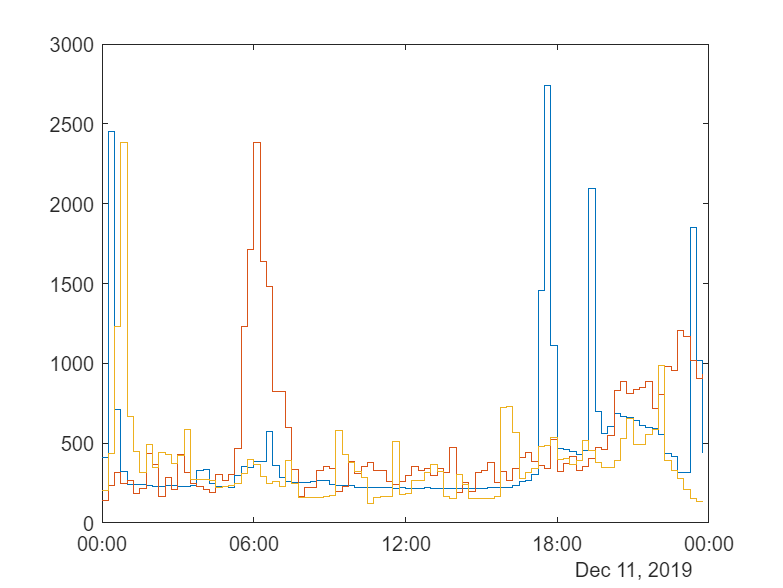

l1 = Bus1_Load1.activepower_p14_l1_mean + Bus1_Load2.activepower_p14_l1_mean;
l2 = Bus1_Load1.activepower_p14_l2_mean + Bus1_Load2.activepower_p14_l2_mean;
l3 = Bus1_Load1.activepower_p14_l3_mean + Bus1_Load2.activepower_p14_l3_mean;
stairs(timestamp,l1)
hold on
stairs(timestamp,l2)
stairs(timestamp,l3)
hold off